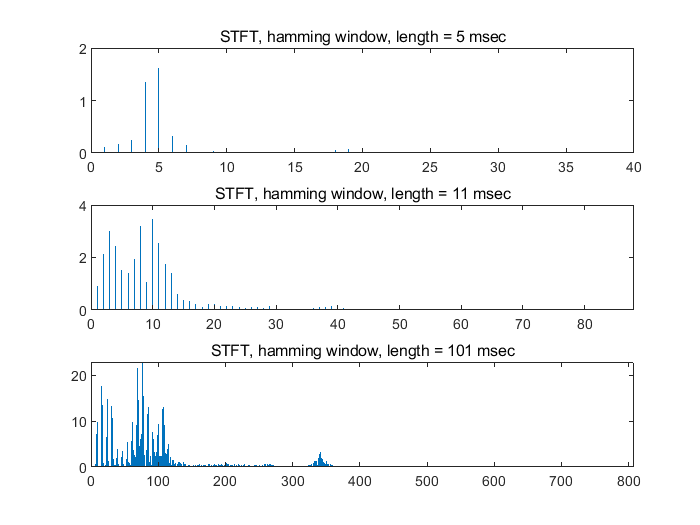


start_sample = 8001;
anal_num = 3;
frame_length = [5 11 101];
%LAB3Q1 calculate the STFT, and generate figures for lab4q1
[signal, Fs] = audioread("s5.wav");
% hamming window plot
figure();
for i = 1:anal_num
 L = round((Fs/1000)*frame_length(i));% calculate length
 window = hamming(L);% generate hamming window
 signal_w = signal(start_sample:start_sample+L-1).*window;% timesignal
 signal_w_s = fft(signal_w);% compute STFT
 
subplot(anal_num,1,i);stem(abs(signal_w_s(1:round(L/2))),'Marker','none');xlim([0,L]);
 title(sprintf('STFT, hamming window, length = %d msec', frame_length(i)));
end

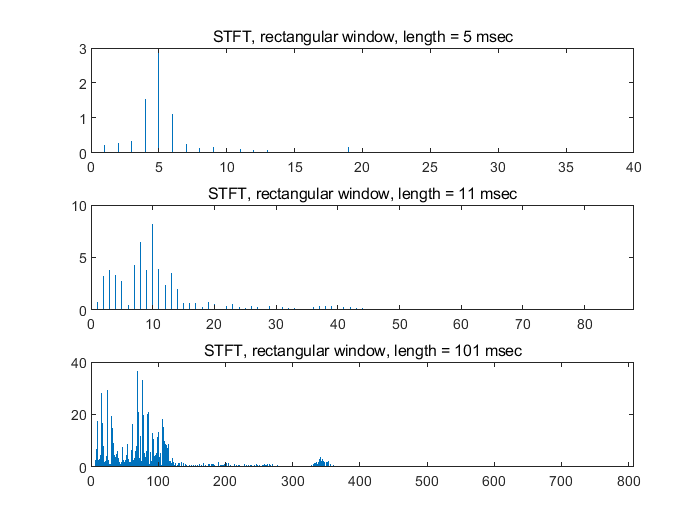


% rectangular window plot
figure;
for i = 1:anal_num
 L = round((Fs/1000)*frame_length(i));% calculate length
 window = ones(L,1);% generate hamming window
 signal_w = signal(start_sample:start_sample+L-1).*window;% timesignal
 signal_w_s = fft(signal_w);% compute STFT
 
subplot(anal_num,1,i);stem(abs(signal_w_s(1:round(L/2))),'Marker','none');
 title(sprintf('STFT, rectangular window, length = %d msec', frame_length(i)));xlim([0,L]);
end

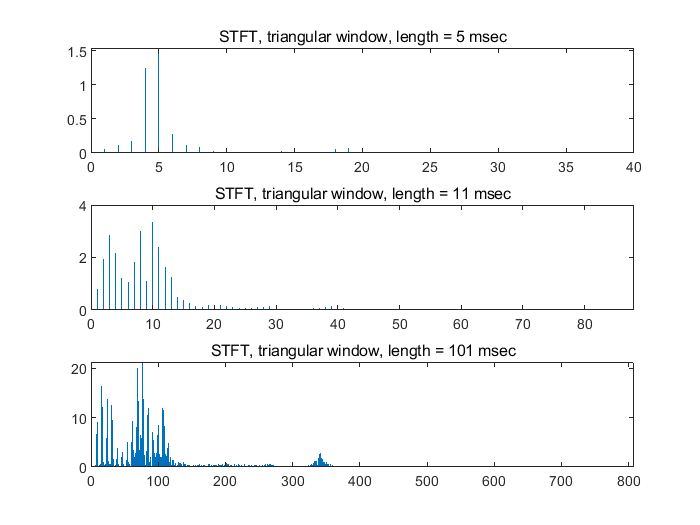


% triangular window plot
figure;
for i = 1:anal_num
 L = round((Fs/1000)*frame_length(i));% calculate length
 window = triang(L);% generate triangular window
 signal_w = signal(start_sample:start_sample+L-1).*window;% timesignal
 signal_w_s = fft(signal_w);% compute STFT
 
subplot(anal_num,1,i);stem(abs(signal_w_s(1:round(L/2))),'Marker','none');xlim([0,L]);
 title(sprintf('STFT, triangular window, length = %d msec', frame_length(i)));
end

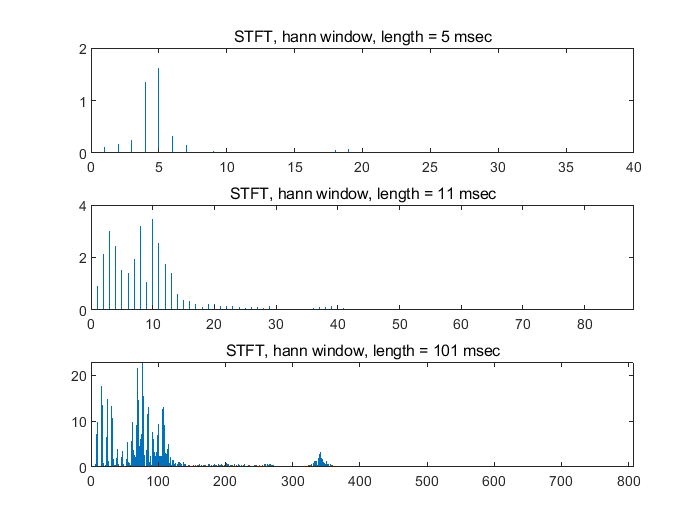


% hann window plot
figure;
for i = 1:anal_num
 L = round((Fs/1000)*frame_length(i));% calculate length
 window = hamming(L);% generate hann window
 signal_w = signal(start_sample:start_sample+L-1).*window;% timesignal
 signal_w_s = fft(signal_w);% compute STFT
 
subplot(anal_num,1,i);stem(abs(signal_w_s(1:round(L/2))),'Marker','none');xlim([0,L]);
 title(sprintf('STFT, hann window, length = %d msec', frame_length(i)));
end

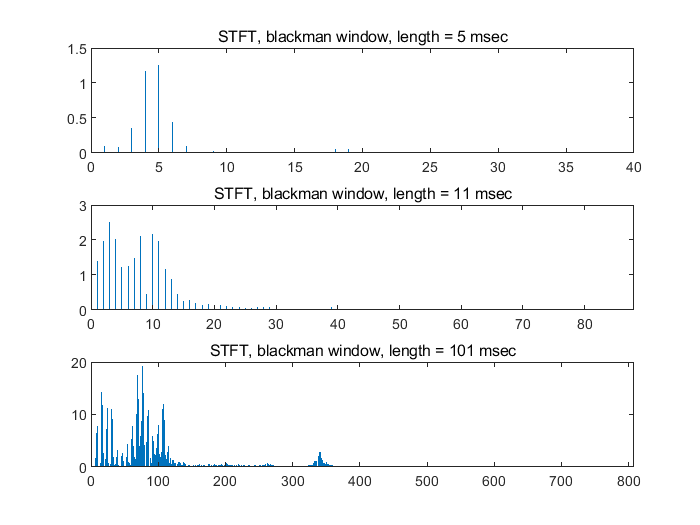


% blackman window plot
figure;
for i = 1:anal_num
 L = round((Fs/1000)*frame_length(i));% calculate length
 window = blackman(L);% generate blackman window
 signal_w = signal(start_sample:start_sample+L-1).*window;% timesignal
 signal_w_s = fft(signal_w);% compute STFT
 
subplot(anal_num,1,i);stem(abs(signal_w_s(1:round(L/2))),'Marker','none');xlim([0,L]);
 title(sprintf('STFT, blackman window, length = %d msec', frame_length(i)));
end